# MAP BULDING LASER BASED 

BY Marc Guitart & Caterina Moll

Link: [https://drive.matlab.com/sharing/a98e15cb-6fdb-4c78-a9c9-590d4af22899](https://drive.matlab.com/sharing/a98e15cb-6fdb-4c78-a9c9-590d4af22899) 

Upload a pdf file of a estructure  Live Script  file to recreate the following results based on the 'Sensors_Data.mat' that you will find in: 

*'' ... MATLAB Drive/Robotica_23_24_1Q/10_Laser Sensors'' *

*Review: Help_Laser_Todo.mlx it has the main concept to deal with laser data*

*Remember the pdf header: **Authors,Team and the s**hared Link **to your**`.mlx’.*

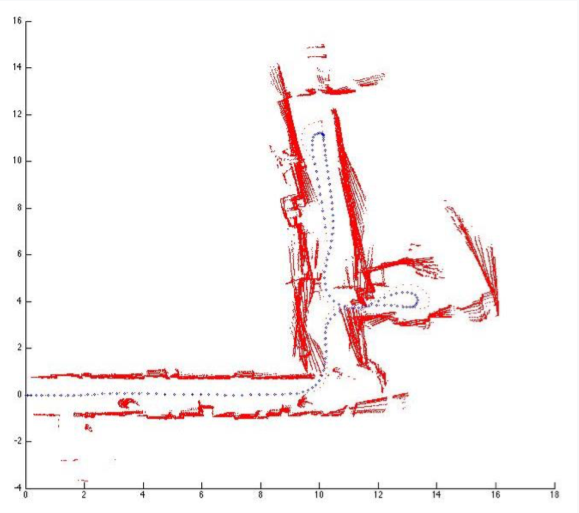

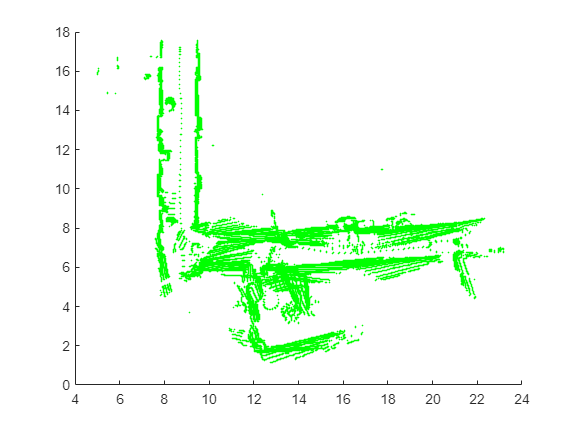

load ("Sensor_Data.mat")

count = 1;
m = size(pose_laser_data);
for i=1:m(1)
    for j=1:(m(2)-1)
        if pose_laser_data(i, j)/1000 > 0 
            alpha = (j-1) * 0.3515 * pi/180;
            incr = 20*i;
            angl_laser = alpha - 122*pi/180;
            dist_laser = v(incr);
            if alpha <= 240/2
                alpha = dist_laser + angl_laser ;
            else
                alpha = dist_laser - angl_laser;
            end
            x_l(count) = x(incr) + pose_laser_data(i, j)/1000 * cos(alpha);
            y_l(count) = y(incr) + pose_laser_data(i, j)/1000 * sin(alpha);
            count = count + 1;
        end
    end
end

figure
Laser_mapped_x = x_l;
Laser_mapped_y = y_l;

scatter(Laser_mapped_x, Laser_mapped_y, 0.7, '.', 'MarkerEdgeColor', 'g')